% 数据
clearvars

XZF3 = importdata('XZF_PAM_30mm.mat');
TEA3 = importdata('TEA_PAM_30mm.mat');
ATP3 = importdata('ATP_PAM_30mm.mat');
CF3 = importdata('CF_PAM_30mm.mat');
XZF2 = importdata('XZF_PAM_20mm.mat');
TEA2 = importdata('TEA_PAM_20mm.mat');
ATP2 = importdata('ATP_PAM_20mm.mat');
CF2 = importdata('CF_PAM_20mm.mat');
XZF1 = importdata('XZF_PAM_10mm.mat');
TEA1 = importdata('TEA_PAM_10mm.mat');
ATP1 = importdata('ATP_PAM_10mm.mat');
CF1 = importdata('CF_PAM_10mm.mat');
% load('XZF_PAM_30mm.mat')
%importfile('XZF_PAM_30mm.mat')

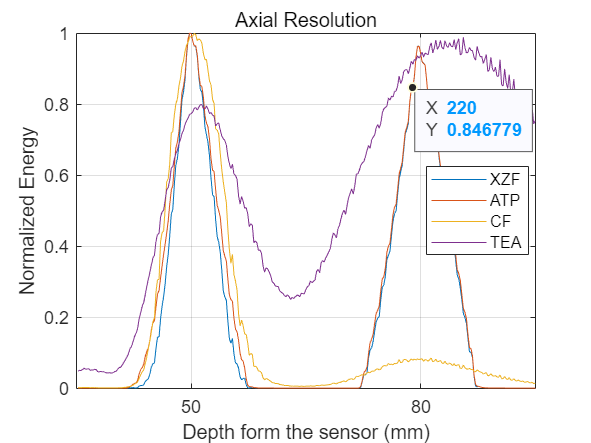


% 绘制图表
figure;
plot( XZF3, 'DisplayName', 'XZF');
hold on;
plot( ATP3,'DisplayName', 'ATP');
plot( CF3,  'DisplayName', 'CF');
plot( TEA3, 'DisplayName', 'TEA');

% 添加标签和图例
xlabel('Depth form the sensor (mm)');
ylabel('Normalized Energy');
title('Axial Resolution');
grid on;
legend('Location', 'Best');
legend('show');

x_ticks = [75,225];
x_tick_labels = {50,80};
xticks(x_ticks);
xticklabels(x_tick_labels);

% 设定轴的范围（如果需要）
% xlim([min(depth), max(depth)]);
% ylim([min([XZF_PAM_resolution, ATP_resolution, CF_resolution, TEA_PAM_resolution]), max([XZF_PAM_resolution, ATP_resolution, CF_resolution, TEA_PAM_resolution])]);

% 如果需要保存图像到文件，可以使用以下代码
% saveas(gcf, 'resolution_vs_depth.png');




% plot the figure 
figure;
plot( XZF2, 'DisplayName', 'XZF');
hold on;
plot( ATP2,'DisplayName', 'ATP');
plot( CF2,  'DisplayName', 'CF');
plot( TEA2, 'DisplayName', 'TEA');
center_axial1 = find(XZF2 >=0.964, 1, 'last')

center_axial1 = 200

center_axial2 = find(XZF2 >= 1, 1, 'first')

center_axial2 = 100

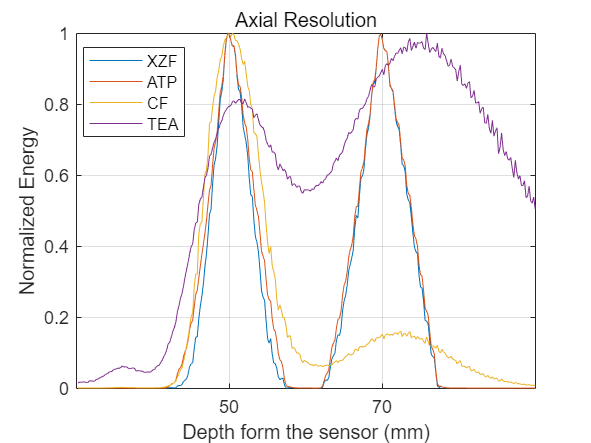

x_ticks = [100,200];
x_tick_labels = {50,70};
xticks(x_ticks);
xticklabels(x_tick_labels);

% labels
xlabel('Depth form the sensor (mm)');
ylabel('Normalized Energy');
title('Axial Resolution');
grid on;
legend('Location', 'Best');

legend('show');

% 设定轴的范围（如果需要）
% xlim([min(depth), max(depth)]);
% ylim([min([XZF_PAM_resolution, ATP_resolution, CF_resolution, TEA_PAM_resolution]), max([XZF_PAM_resolution, ATP_resolution, CF_resolution, TEA_PAM_resolution])]);

% 如果需要保存图像到文件，可以使用以下代码
% saveas(gcf, 'resolution_vs_depth.png');


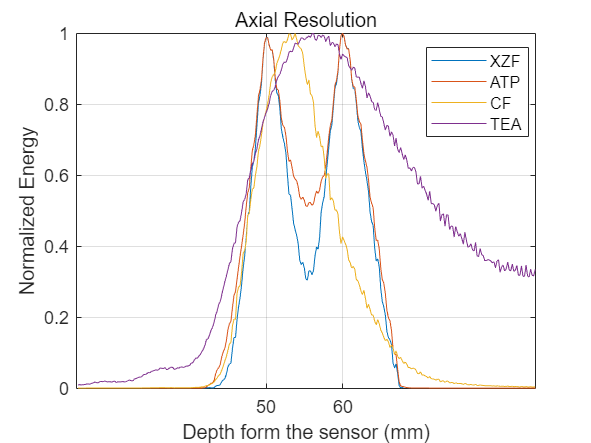

figure;
plot( XZF1, 'DisplayName', 'XZF');
hold on;
plot( ATP1,'DisplayName', 'ATP');
plot( CF1,  'DisplayName', 'CF');
plot( TEA1, 'DisplayName', 'TEA');

x_ticks = [124,174];
x_tick_labels = {50,60};
xticks(x_ticks);
xticklabels(x_tick_labels);

% 添加标签和图例
xlabel('Depth form the sensor (mm)');
ylabel('Normalized Energy');
title('Axial Resolution');
grid on;
legend('Location', 'Best');

legend('show');


function importfile(fileToRead1)
%IMPORTFILE(FILETOREAD1)
%  从指定文件中导入数据
%  FILETOREAD1:  要读取的文件

%  由 MATLAB 于 10-Sep-2023 22:09:30 自动生成

% 导入文件
newData1 = load('-mat', fileToRead1);

% 在基础工作区中从这些字段创建新变量。
vars = fieldnames(newData1);
for i = 1:length(vars)
    assignin('base', vars{i}, newData1.(vars{i}));
end
end